%Inverse Kinematics
robot.ikineType = 'nooffset'

 
robot = 
 
AltusBot:: 6 axis, RRRRRR, stdDH, slowRNE                        
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|    0.06781|      0.038|     1.5708|          0|
|  2|         q2|          0|        0.3|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|        0.2|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
tool:    t = (0, 0, 0.09), RPY/xyz = (0, 0, 0) deg               
 


qs = [0 pi/2 0 0 0 0]; %ready angle(straight up)
Ts = robot.fkine(qs) %Must Match Below qi2 T matrix

 

Ts = 
         0         0         1     0.328
         0        -1         0         0
         1         0         0    0.3678
         0         0         0         1


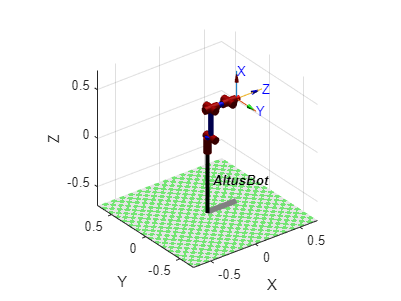

%Pose I want IK solution to Get
robot.plot(qs)

qs_deg = qs*180/pi

qs_deg =      0    90     0     0     0     0


q1_deg = [6.8 54 -32.4 0 -21.6 0]

q1_deg =     6.8000   54.0000  -32.4000         0  -21.6000         0


q1 = q1_deg*pi/180

q1 =     0.1187    0.9425   -0.5655         0   -0.3770         0


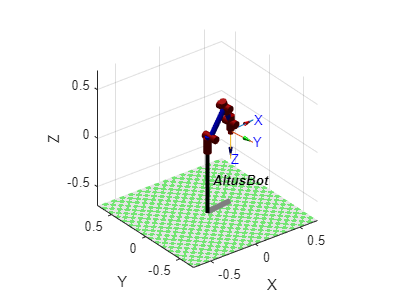

robot.plot(q1)

q2_deg = [-37.4 51 -18 0 -32.4 0]

q2_deg =   -37.4000   51.0000  -18.0000         0  -32.4000         0


q2 = q2_deg*pi/180

q2 =    -0.6528    0.8901   -0.3142         0   -0.5655         0


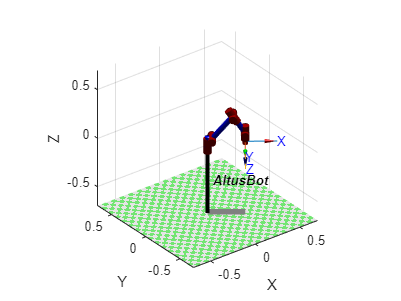

robot.plot(q2)

q3_deg = [0 55 -25 0 -21.6 0]

q3_deg =          0   55.0000  -25.0000         0  -21.6000         0


q3 = q3_deg*pi/180

q3 =          0    0.9599   -0.4363         0   -0.3770         0


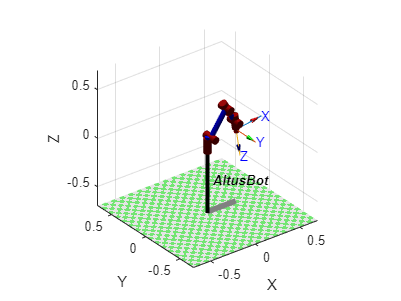

robot.plot(q3)

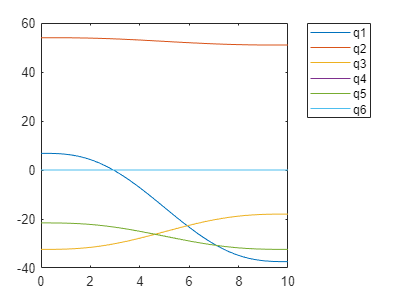

t = [0:0.05:10]; % over 2 sec period in 50ms increments
[qh,qd,qdd]=jtraj(q1,q2,t); %pos,vel,accel
qh = qh*180/pi;
plot(t, qh) %plots all 6 joint angles over t
legend(["q1","q2","q3","q4","q5","q6"])

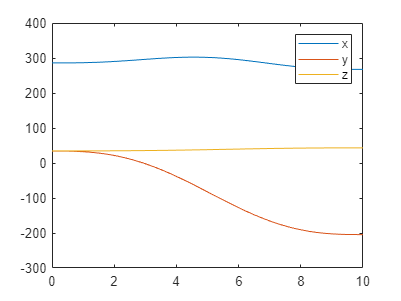

qh = qh*pi/180;
T = robot.fkine(qh);
p = T.transl; % gets only translational part of transformation matrix T
p = p*1000;
plot(t,p) %plots xyz vs time
legend(["x","y","z"])

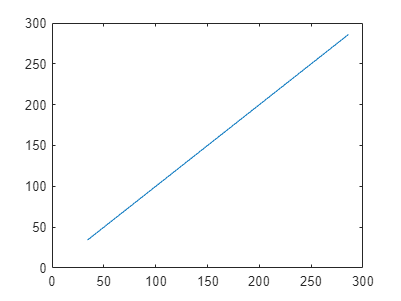

plot(p(1,:),p(2,:)) %plots path of end-effector in xy plane

qs_deg_rounded = round(qs_deg,2);
stringData = qs_deg_rounded(1) + "," + qs_deg_rounded(2) + "," + qs_deg_rounded(3) + "," + qs_deg_rounded(4) + "," + qs_deg_rounded(5) + "," + qs_deg_rounded(6) ;
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,0,90,0,0,0,0"

serial_send(stringData,s);

MJ,0,90,0,0,0,0



pause(10)

q1_deg_rounded = round(q1_deg,2);
stringData = q1_deg_rounded(1) + "," + q1_deg_rounded(2) + "," + q1_deg_rounded(3) + "," + q1_deg_rounded(4) + "," + q1_deg_rounded(5) + "," + q1_deg_rounded(6) ;
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,6.8,54,-32.4,0,-21.6,0"

serial_send(stringData,s);

MJ,6.8,54,-32.4,0,-21.6,0



pause(8)

serial_send("CG",s);

CG


pause(1)

q3_deg_rounded = round(q3_deg,2);
stringData = q3_deg_rounded(1) + "," + q3_deg_rounded(2) + "," + q3_deg_rounded(3) + "," + q3_deg_rounded(4) + "," + q3_deg_rounded(5) + "," + q3_deg_rounded(6); 
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,0,55,-25,0,-21.6,0"

serial_send(stringData,s);

MJ,0,55,-25,0,-21.6,0



pause(1)

q2_deg_rounded = round(q2_deg,2);
stringData = q2_deg_rounded(1) + "," + q2_deg_rounded(2) + "," + q2_deg_rounded(3) + "," + q2_deg_rounded(4) + "," + q2_deg_rounded(5) + "," + q2_deg_rounded(6); 
stringCommand = "MJ";
stringData = stringCommand + "," + stringData

stringData = "MJ,-37.4,51,-18,0,-32.4,0"

serial_send(stringData,s);

MJ,-37.4,51,-18,0,-32.4,0



pause(5)

serial_send("OG",s);

OG
